# Room Impulse Response Measurements

close all; clear; clc;
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
clear list_factory index_interpreter default_name i;

% Add paths
addpath(genpath('Data'));

% Settings
SETTINGS.titleFS    = 18;
SETTINGS.subtitleFS = 15;
SETTINGS.labelFS    = 12;

## Load data

Data is taken from the **Impulse Response Measurer**, and the measurements are taken on the 3rd of May between 15:00 and 16:00 at Fredrik Bajersvej 7b, B4-107.

load('Measurement1');
load('Measurement2');
load('Measurement3');
load('Measurement4');
load('Measurement5');

colors = distinguishable_colors(5, 'w');

## Measurement 1

CurrentMeasurement = Measurement1;
plotColor = colors(1, :);

Measurement taken at:

display(CurrentMeasurement.TimeOfCapture)

  datetime

   09-May-2023 12:04:36 UTC+02:00



Device (driver):

display(CurrentMeasurement.Device)

    "FL Studio ASIO"



Sample rate:

fs = CurrentMeasurement.SampleRate;
display(fs)

fs = 44100

Samples per frame:

display(CurrentMeasurement.SamplesPerFrame)

        1024



Player and recorder channels (amount):

display(CurrentMeasurement.PlayerChannels)

  1×1 cell array

    {[1]}



display(CurrentMeasurement.RecorderChannel)

     1



Method used:

display(CurrentMeasurement.Method)

    "Swept Sine"



Number of runs:

display(CurrentMeasurement.NumRuns)

     5



Excitation level [dB]

display(CurrentMeasurement.ExcitationLevel)

    -6



#### Signal Plots

input       = CurrentMeasurement.RawAudioData.ExcitationSignal;
recorded    = CurrentMeasurement.RawAudioData.RecordedSignal;
t           = (0:size(input, 1)-1)'/fs;

The input signal plotted:

f = figure('Position', [10 10 900 300]);
plot(t, input, 'r');
grid on;
title('Excitation Signal', 'FontSize', SETTINGS.titleFS);
ylim([-1 1])
xlim([0 t(end)]);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/ExcitationSignal.pdf', 'Resolution', 300);

The recorded signals:

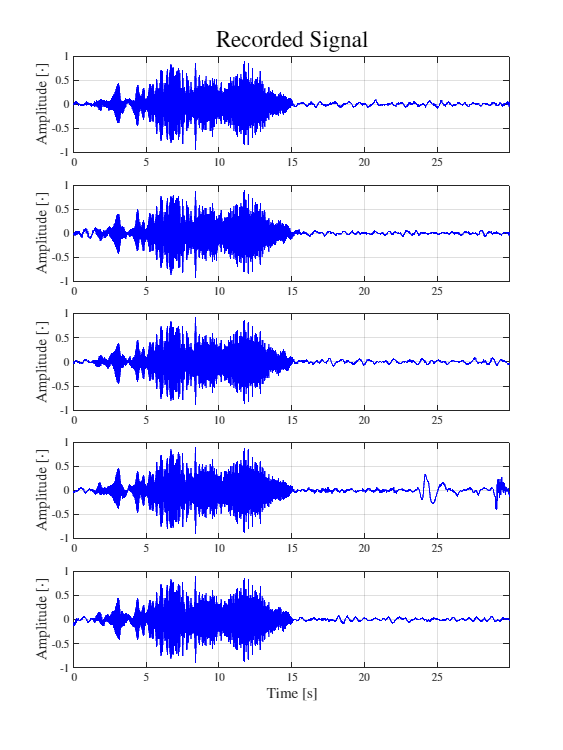

f = figure('Position', [10 10 900 1200]);
tiledlayout(5, 1);

nexttile;
p = plot(t, recorded(:, 1, 1));
p.Color = plotColor;
grid on;
title('Recorded Signal', 'FontSize', SETTINGS.titleFS);
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 2));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 3));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 4));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 5));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

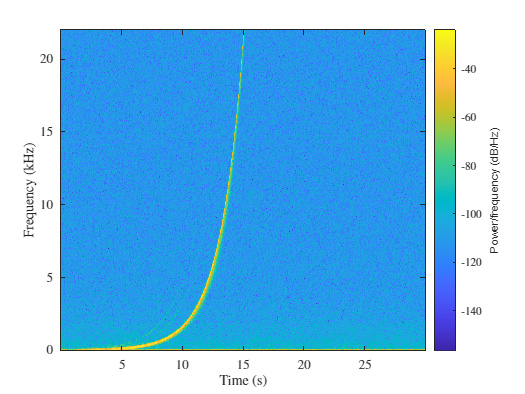

%exportgraphics(f, 'Figures/RecordedSignal_Meas5.pdf', 'Resolution', 300);

figure();
spectrogram(recorded(:, 1, 1), blackman(1000), 1, 2^(12), fs,'yaxis')

#### Impulse Response, Magnitude Response, and Phase Response

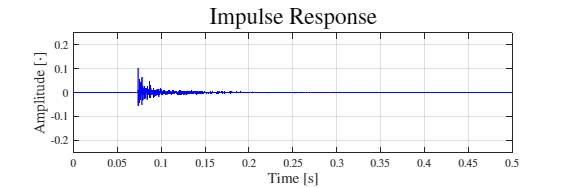

IR = CurrentMeasurement.ImpulseResponse;
MR = CurrentMeasurement.MagnitudeResponse;
PR = CurrentMeasurement.PhaseResponse;

f = figure('Position', [10 10 900 300]);
p = plot(IR.Time, IR.Amplitude);
p.Color = plotColor;
grid on;
xlim([0 0.5])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

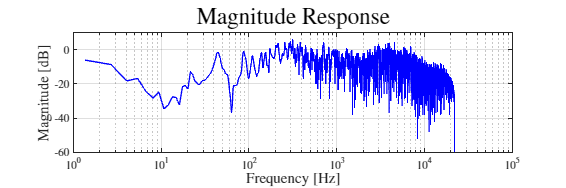

%exportgraphics(f, 'Figures/ImpulseResponse_Meas1.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(MR.Frequency, MR.MagnitudeDB);
s.Color = plotColor;
grid on;
ylim([-60 10]);
% xlim([0.05 0.07])
title('Magnitude Response', 'FontSize', SETTINGS.titleFS);
ylabel('Magnitude $[\mathrm{dB}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

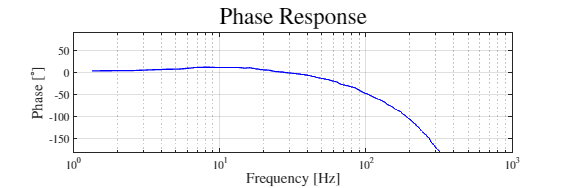

%exportgraphics(f, 'Figures/MagnitudeResponse_Meas1.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(PR.Frequency, PR.Phase);
s.Color = plotColor;
grid on;
ylim([-180 90])
% xlim([0.05 0.07])
title('Phase Response', 'FontSize', SETTINGS.titleFS);
ylabel('Phase $[\mathrm{^\circ}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/PhaseResponse_Meas1.pdf', 'Resolution', 300);

## Measurement 2

CurrentMeasurement = Measurement2;
plotColor = colors(2, :);

Measurement taken at:

display(CurrentMeasurement.TimeOfCapture)

  datetime

   09-May-2023 12:08:22 UTC+02:00



Device (driver):

display(CurrentMeasurement.Device)

    "FL Studio ASIO"



Sample rate:

fs = CurrentMeasurement.SampleRate;
display(fs)

fs = 44100

Samples per frame:

display(CurrentMeasurement.SamplesPerFrame)

        1024



Player and recorder channels (amount):

display(CurrentMeasurement.PlayerChannels)

  1×1 cell array

    {[1]}



display(CurrentMeasurement.RecorderChannel)

     1



Method used:

display(CurrentMeasurement.Method)

    "Swept Sine"



Number of runs:

display(CurrentMeasurement.NumRuns)

     5



Excitation level [dB]

display(CurrentMeasurement.ExcitationLevel)

    -6



#### Signal Plots

input       = CurrentMeasurement.RawAudioData.ExcitationSignal;
recorded    = CurrentMeasurement.RawAudioData.RecordedSignal;
t           = (0:size(input, 1)-1)'/fs;

The input signal plotted:

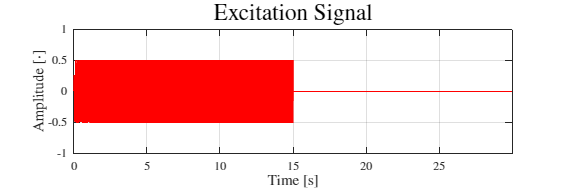

f = figure('Position', [10 10 900 300]);
plot(t, input, 'r');
grid on;
title('Excitation Signal', 'FontSize', SETTINGS.titleFS);
ylim([-1 1])
xlim([0 t(end)]);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/ExcitationSignal.pdf', 'Resolution', 300);

The recorded signals:

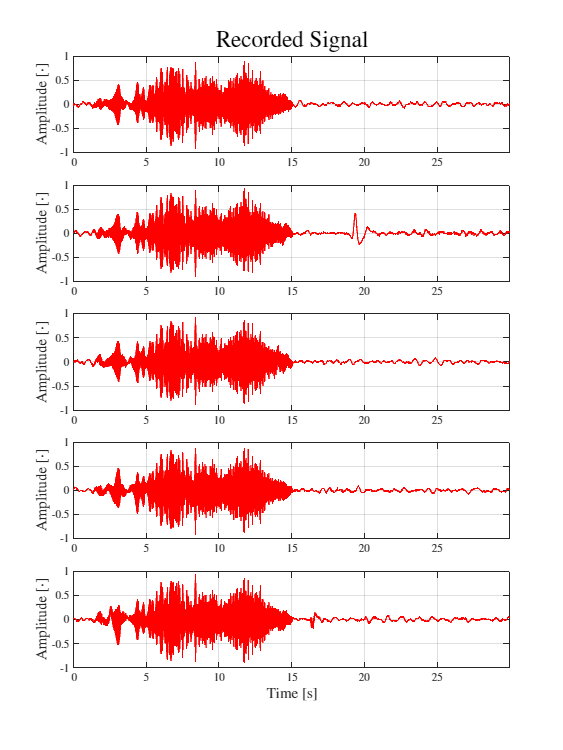

f = figure('Position', [10 10 900 1200]);
tiledlayout(5, 1);

nexttile;
p = plot(t, recorded(:, 1, 1));
p.Color = plotColor;
grid on;
title('Recorded Signal', 'FontSize', SETTINGS.titleFS);
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 2));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 3));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 4));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 5));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/RecordedSignal_Meas2.pdf', 'Resolution', 300);

#### Impulse Response, Magnitude Response, and Phase Response

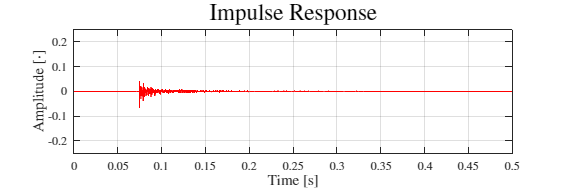

IR = CurrentMeasurement.ImpulseResponse;
MR = CurrentMeasurement.MagnitudeResponse;
PR = CurrentMeasurement.PhaseResponse;

f = figure('Position', [10 10 900 300]);
p = plot(IR.Time, IR.Amplitude);
p.Color = plotColor;
grid on;
xlim([0 0.5])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

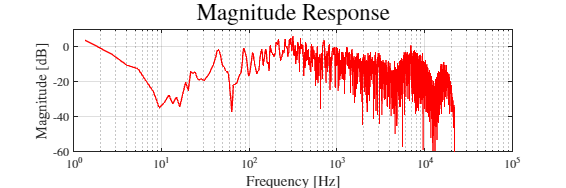

%exportgraphics(f, 'Figures/ImpulseResponse_Meas2.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(MR.Frequency, MR.MagnitudeDB);
s.Color = plotColor;
grid on;
ylim([-60 10]);
% xlim([0.05 0.07])
title('Magnitude Response', 'FontSize', SETTINGS.titleFS);
ylabel('Magnitude $[\mathrm{dB}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

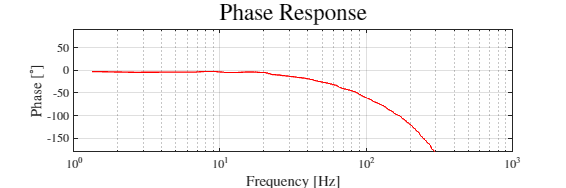

%exportgraphics(f, 'Figures/MagnitudeResponse_Meas2.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(PR.Frequency, PR.Phase);
s.Color = plotColor;
grid on;
ylim([-180 90])
% xlim([0.05 0.07])
title('Phase Response', 'FontSize', SETTINGS.titleFS);
ylabel('Phase $[\mathrm{^\circ}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/PhaseResponse_Meas2.pdf', 'Resolution', 300);

## Measurement 3

CurrentMeasurement = Measurement3;
plotColor = colors(3, :);

Measurement taken at:

display(CurrentMeasurement.TimeOfCapture)

  datetime

   09-May-2023 12:11:49 UTC+02:00



Device (driver):

display(CurrentMeasurement.Device)

    "FL Studio ASIO"



Sample rate:

fs = CurrentMeasurement.SampleRate;
display(fs)

fs = 44100

Samples per frame:

display(CurrentMeasurement.SamplesPerFrame)

        1024



Player and recorder channels (amount):

display(CurrentMeasurement.PlayerChannels)

  1×1 cell array

    {[1]}



display(CurrentMeasurement.RecorderChannel)

     1



Method used:

display(CurrentMeasurement.Method)

    "Swept Sine"



Number of runs:

display(CurrentMeasurement.NumRuns)

     5



Excitation level [dB]

display(CurrentMeasurement.ExcitationLevel)

    -6



#### Signal Plots

input       = CurrentMeasurement.RawAudioData.ExcitationSignal;
recorded    = CurrentMeasurement.RawAudioData.RecordedSignal;
t           = (0:size(input, 1)-1)'/fs;

The input signal plotted:

f = figure('Position', [10 10 900 300]);
plot(t, input, 'r');
grid on;
title('Excitation Signal', 'FontSize', SETTINGS.titleFS);
ylim([-1 1])
xlim([0 t(end)]);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/ExcitationSignal.pdf', 'Resolution', 300);

The recorded signals:

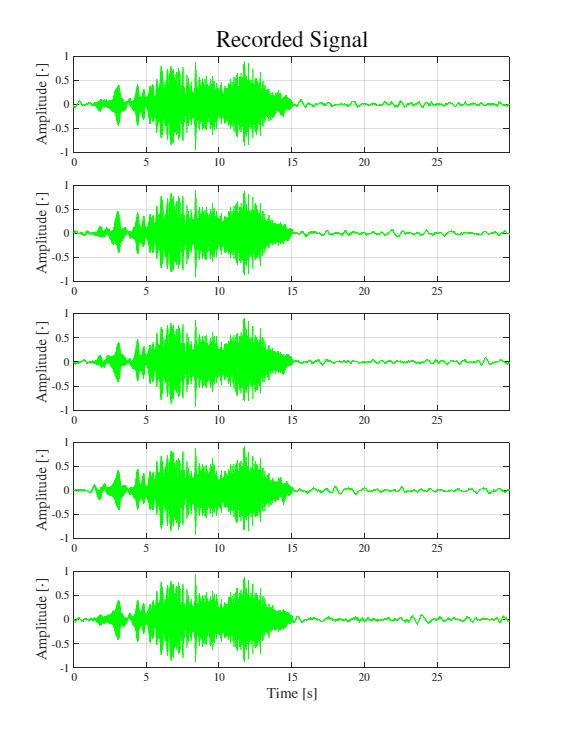

f = figure('Position', [10 10 900 1200]);
tiledlayout(5, 1);

nexttile;
p = plot(t, recorded(:, 1, 1));
p.Color = plotColor;
grid on;
title('Recorded Signal', 'FontSize', SETTINGS.titleFS);
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 2));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 3));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 4));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 5));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/RecordedSignal_Meas3.pdf', 'Resolution', 300);

#### Impulse Response, Magnitude Response, and Phase Response

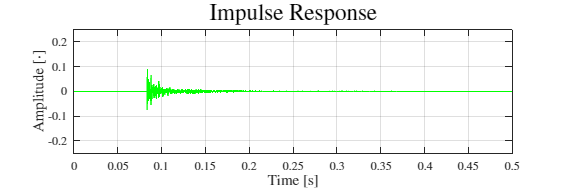

IR = CurrentMeasurement.ImpulseResponse;
MR = CurrentMeasurement.MagnitudeResponse;
PR = CurrentMeasurement.PhaseResponse;

f = figure('Position', [10 10 900 300]);
p = plot(IR.Time, IR.Amplitude);
p.Color = plotColor;
grid on;
xlim([0 0.5])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

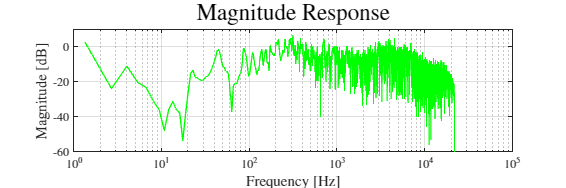

%exportgraphics(f, 'Figures/ImpulseResponse_Meas3.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(MR.Frequency, MR.MagnitudeDB);
s.Color = plotColor;
grid on;
ylim([-60 10]);
% xlim([0.05 0.07])
title('Magnitude Response', 'FontSize', SETTINGS.titleFS);
ylabel('Magnitude $[\mathrm{dB}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

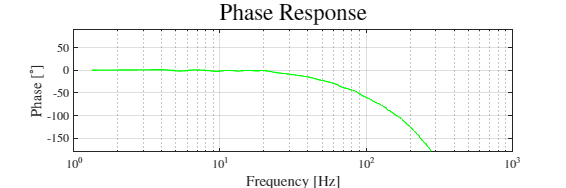

%exportgraphics(f, 'Figures/MagnitudeResponse_Meas3.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(PR.Frequency, PR.Phase);
s.Color = plotColor;
grid on;
ylim([-180 90])
% xlim([0.05 0.07])
title('Phase Response', 'FontSize', SETTINGS.titleFS);
ylabel('Phase $[\mathrm{^\circ}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/PhaseResponse_Meas3.pdf', 'Resolution', 300);

## Measurement 4

CurrentMeasurement = Measurement4;
plotColor = colors(4, :);

Measurement taken at:

display(CurrentMeasurement.TimeOfCapture)

  datetime

   09-May-2023 12:15:16 UTC+02:00



Device (driver):

display(CurrentMeasurement.Device)

    "FL Studio ASIO"



Sample rate:

fs = CurrentMeasurement.SampleRate;
display(fs)

fs = 44100

Samples per frame:

display(CurrentMeasurement.SamplesPerFrame)

        1024



Player and recorder channels (amount):

display(CurrentMeasurement.PlayerChannels)

  1×1 cell array

    {[1]}



display(CurrentMeasurement.RecorderChannel)

     1



Method used:

display(CurrentMeasurement.Method)

    "Swept Sine"



Number of runs:

display(CurrentMeasurement.NumRuns)

     5



Excitation level [dB]

display(CurrentMeasurement.ExcitationLevel)

    -6



#### Signal Plots

input       = CurrentMeasurement.RawAudioData.ExcitationSignal;
recorded    = CurrentMeasurement.RawAudioData.RecordedSignal;
t           = (0:size(input, 1)-1)'/fs;

The input signal plotted:

f = figure('Position', [10 10 900 300]);
plot(t, input, 'r');
grid on;
title('Excitation Signal', 'FontSize', SETTINGS.titleFS);
ylim([-1 1])
xlim([0 t(end)]);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/ExcitationSignal.pdf', 'Resolution', 300);

The recorded signals:

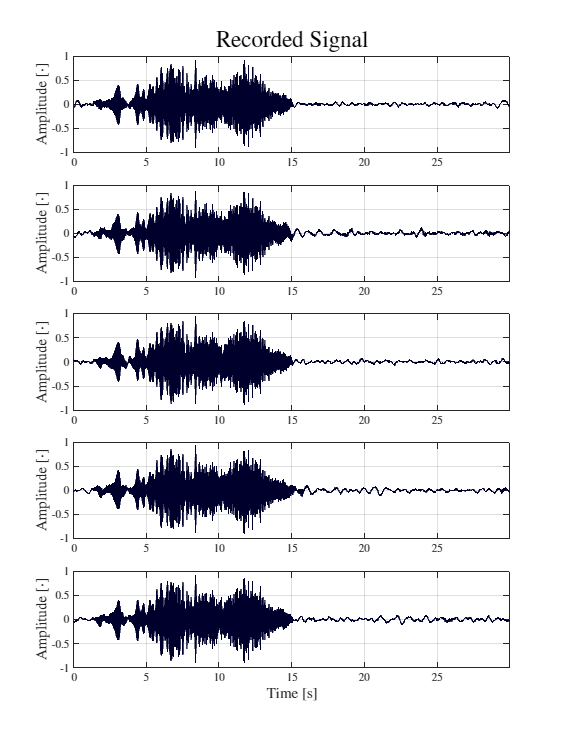

f = figure('Position', [10 10 900 1200]);
tiledlayout(5, 1);

nexttile;
p = plot(t, recorded(:, 1, 1));
p.Color = plotColor;
grid on;
title('Recorded Signal', 'FontSize', SETTINGS.titleFS);
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 2));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 3));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 4));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 5));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/RecordedSignal_Meas4.pdf', 'Resolution', 300);

#### Impulse Response, Magnitude Response, and Phase Response

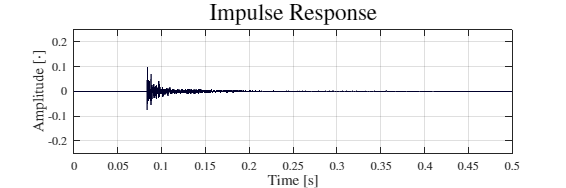

IR = CurrentMeasurement.ImpulseResponse;
MR = CurrentMeasurement.MagnitudeResponse;
PR = CurrentMeasurement.PhaseResponse;

f = figure('Position', [10 10 900 300]);
p = plot(IR.Time, IR.Amplitude);
p.Color = plotColor;
grid on;
xlim([0 0.5])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

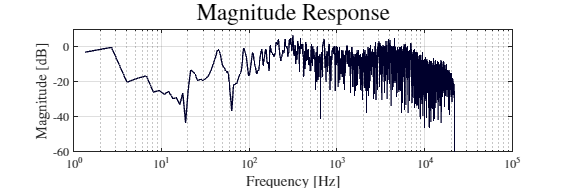

%exportgraphics(f, 'Figures/ImpulseResponse_Meas4.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(MR.Frequency, MR.MagnitudeDB);
s.Color = plotColor;
grid on;
ylim([-60 10]);
% xlim([0.05 0.07])
title('Magnitude Response', 'FontSize', SETTINGS.titleFS);
ylabel('Magnitude $[\mathrm{dB}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

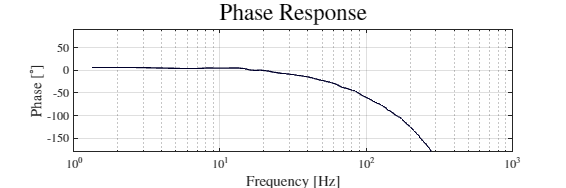

%exportgraphics(f, 'Figures/MagnitudeResponse_Meas4.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(PR.Frequency, PR.Phase);
s.Color = plotColor;
grid on;
ylim([-180 90])
% xlim([0.05 0.07])
title('Phase Response', 'FontSize', SETTINGS.titleFS);
ylabel('Phase $[\mathrm{^\circ}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/PhaseResponse_Meas4.pdf', 'Resolution', 300);

## Measurement 5

CurrentMeasurement = Measurement5;
plotColor = colors(5, :);

Measurement taken at:

display(CurrentMeasurement.TimeOfCapture)

  datetime

   09-May-2023 12:18:43 UTC+02:00



Device (driver):

display(CurrentMeasurement.Device)

    "FL Studio ASIO"



Sample rate:

fs = CurrentMeasurement.SampleRate;
display(fs)

fs = 44100

Samples per frame:

display(CurrentMeasurement.SamplesPerFrame)

        1024



Player and recorder channels (amount):

display(CurrentMeasurement.PlayerChannels)

  1×1 cell array

    {[1]}



display(CurrentMeasurement.RecorderChannel)

     1



Method used:

display(CurrentMeasurement.Method)

    "Swept Sine"



Number of runs:

display(CurrentMeasurement.NumRuns)

     5



Excitation level [dB]

display(CurrentMeasurement.ExcitationLevel)

    -6



#### Signal Plots

input       = CurrentMeasurement.RawAudioData.ExcitationSignal;
recorded    = CurrentMeasurement.RawAudioData.RecordedSignal;
t           = (0:size(input, 1)-1)'/fs;

The input signal plotted:

f = figure('Position', [10 10 900 300]);
plot(t, input, 'r');
grid on;
title('Excitation Signal', 'FontSize', SETTINGS.titleFS);
ylim([-1 1])
xlim([0 t(end)]);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/ExcitationSignal.pdf', 'Resolution', 300);

The recorded signals:

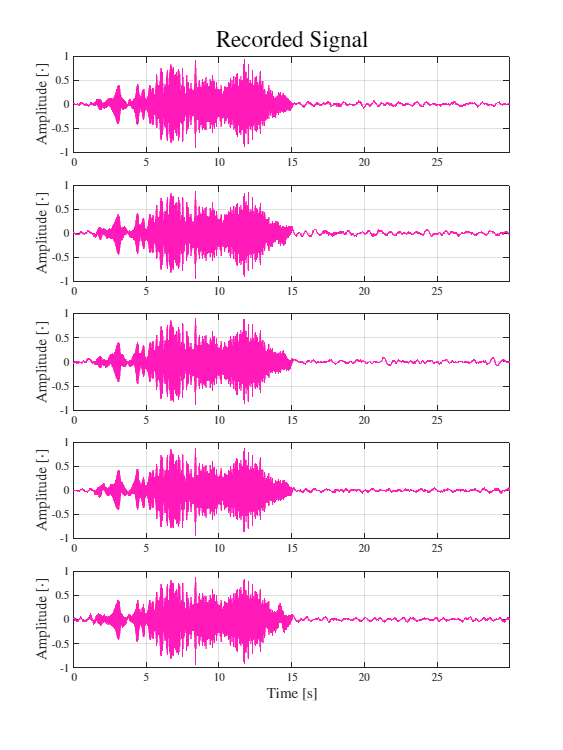

f = figure('Position', [10 10 900 1200]);
tiledlayout(5, 1);

nexttile;
p = plot(t, recorded(:, 1, 1));
p.Color = plotColor;
grid on;
title('Recorded Signal', 'FontSize', SETTINGS.titleFS);
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 2));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 3));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 4));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(t, recorded(:, 1, 5));
p.Color = plotColor;
grid on;
xlim([0 t(end)]);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/RecordedSignal_Meas5.pdf', 'Resolution', 300);

#### Impulse Response, Magnitude Response, and Phase Response

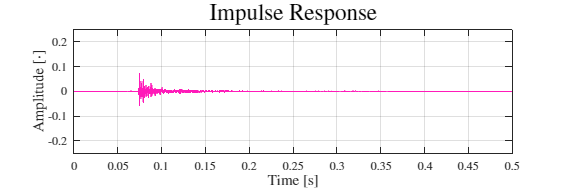

IR = CurrentMeasurement.ImpulseResponse;
MR = CurrentMeasurement.MagnitudeResponse;
PR = CurrentMeasurement.PhaseResponse;

f = figure('Position', [10 10 900 300]);
p = plot(IR.Time, IR.Amplitude);
p.Color = plotColor;
grid on;
xlim([0 0.5])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);

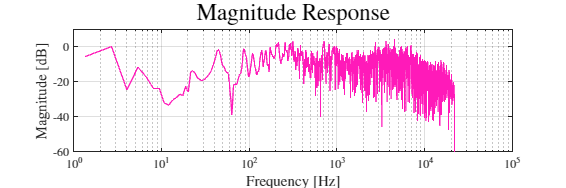

%exportgraphics(f, 'Figures/ImpulseResponse_Meas5.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(MR.Frequency, MR.MagnitudeDB);
s.Color = plotColor;
grid on;
ylim([-60 10]);
% xlim([0.05 0.07])
title('Magnitude Response', 'FontSize', SETTINGS.titleFS);
ylabel('Magnitude $[\mathrm{dB}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

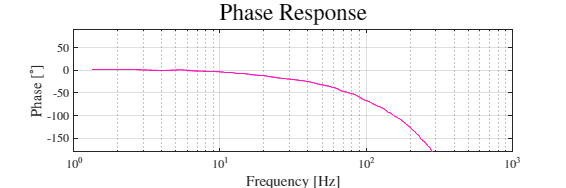

%exportgraphics(f, 'Figures/MagnitudeResponse_Meas5.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(PR.Frequency, PR.Phase);
s.Color = plotColor;
grid on;
ylim([-180 90])
% xlim([0.05 0.07])
title('Phase Response', 'FontSize', SETTINGS.titleFS);
ylabel('Phase $[\mathrm{^\circ}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);

%exportgraphics(f, 'Figures/PhaseResponse_Meas5.pdf', 'Resolution', 300);

## IR, MR and PR together across measurements

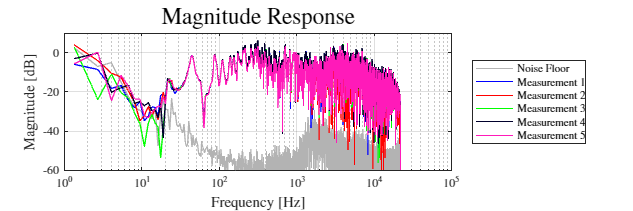

load('NoiseFloor.mat');
MR_floor = measurementData.MagnitudeResponse;

IR = [Measurement1.ImpulseResponse
      Measurement2.ImpulseResponse
      Measurement3.ImpulseResponse
      Measurement4.ImpulseResponse
      Measurement5.ImpulseResponse];
MR = [Measurement1.MagnitudeResponse
      Measurement2.MagnitudeResponse
      Measurement3.MagnitudeResponse
      Measurement4.MagnitudeResponse
      Measurement5.MagnitudeResponse
      measurementData.MagnitudeResponse];
PR = [Measurement1.PhaseResponse
      Measurement2.PhaseResponse
      Measurement3.PhaseResponse
      Measurement4.PhaseResponse
      Measurement5.PhaseResponse];
save('Responses\ImpulseResponses', "IR");
save('Responses\MagnitudeResponses', "MR");
save('Responses\PhaseResponses', "PR");


f = figure('Position', [10 10 900 300]);
s = semilogx(MR_floor.Frequency, MR_floor.MagnitudeDB);
s.Color = [1 1 1].*0.7;
hold on
    s = semilogx(MR(1).Frequency, MR(1).MagnitudeDB);
    s.Color = colors(1, :);
    s = semilogx(MR(2).Frequency, MR(2).MagnitudeDB);
    s.Color = colors(2, :);
    s = semilogx(MR(3).Frequency, MR(3).MagnitudeDB);
    s.Color = colors(3, :);
    s = semilogx(MR(4).Frequency, MR(4).MagnitudeDB);
    s.Color = colors(4, :);
    s = semilogx(MR(5).Frequency, MR(5).MagnitudeDB);
    s.Color = colors(5, :);
hold off
grid on;
ylim([-60 10]);
% xlim([0.05 0.07])
title('Magnitude Response', 'FontSize', SETTINGS.titleFS);
ylabel('Magnitude $[\mathrm{dB}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);
legend('Noise Floor', 'Measurement 1', 'Measurement 2', 'Measurement 3', 'Measurement 4', 'Measurement 5','Location', 'eastoutside')

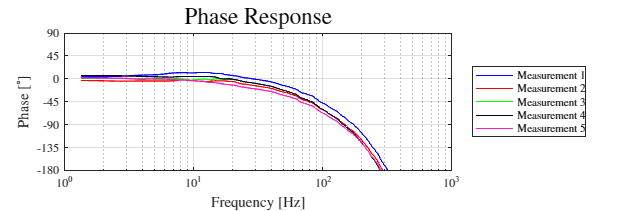

% exportgraphics(f, 'Figures/MagnitudeResponse_All_withFloor.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
s = semilogx(PR(1).Frequency, PR(1).Phase);
s.Color = colors(1, :);
hold on
for i = 2:5
    s = semilogx(PR(i).Frequency, PR(i).Phase);
    s.Color = colors(i, :);
end
hold off
grid on;
ylim([-180 90])
yticks(-180:45:90)
% xlim([0.05 0.07])
title('Phase Response', 'FontSize', SETTINGS.titleFS);
ylabel('Phase $[\mathrm{^\circ}]$', 'FontSize', SETTINGS.labelFS);
xlabel('Frequency $[\mathrm{Hz}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 1', 'Measurement 2', 'Measurement 3', 'Measurement 4', 'Measurement 5', 'Location', 'eastoutside')

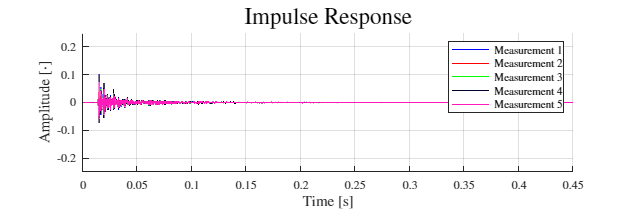

%exportgraphics(f, 'Figures/PhaseResponse_All.pdf', 'Resolution', 300);


% Correcting time delay
I = zeros(5, 1);
for i = 1:5
    [~, I(i)]    = max(IR(i).Amplitude);
    IR(i).Time      = IR(i).Time - IR(i).Time(I(i)) + (7.79-1.28*2)/343;
end



f = figure('Position', [10 10 900 300]);
hold on
    p = plot(IR(1).Time, IR(1).Amplitude);
    p.Color = colors(1, :);
    p = plot(IR(2).Time, IR(2).Amplitude);
    p.Color = colors(2, :);
    p = plot(IR(3).Time, IR(3).Amplitude);
    p.Color = colors(3, :);
    p = plot(IR(4).Time, IR(4).Amplitude);
    p.Color = colors(4, :);
    p = plot(IR(5).Time, IR(5).Amplitude);
    p.Color = colors(5, :);
hold off
grid on;
xlim([0 0.45])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 1', 'Measurement 2', 'Measurement 3', 'Measurement 4', 'Measurement 5', 'Location', 'northeast')

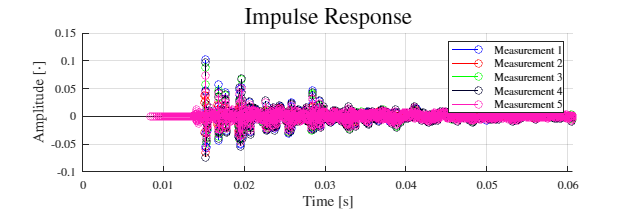

%exportgraphics(f, 'Figures/ImpulseResponse_All.pdf', 'Resolution', 300);

% MED STEM
f = figure('Position', [10 10 900 300]);
hold on
for i = 1:5
    signal = [IR(i).Time IR(i).Amplitude];
    signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
    p = stem(signal(:, 1), signal(:, 2));
    p.Color = colors(i, :);
end
hold off
grid on;
xlim([0 20.81/343])
ylim([-0.1 0.15])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 1', 'Measurement 2', 'Measurement 3', 'Measurement 4', 'Measurement 5', 'Location', 'northeast')

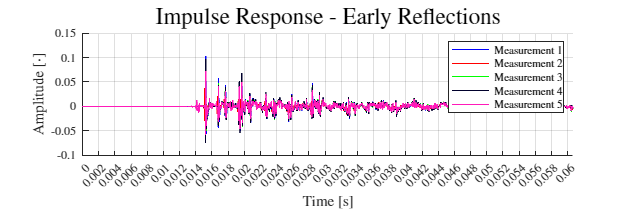

%exportgraphics(f, 'Figures/ImpulseResponse_All_stem.pdf', 'Resolution', 300);

% MED STEM
f = figure('Position', [10 10 900 300]);
hold on
for i = 1:5
    signal = [IR(i).Time IR(i).Amplitude];
    signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
    p = plot(signal(:, 1), signal(:, 2));
    p.Color = colors(i, :);
end
hold off
grid on;
xlim([0 20.81/343])
% xlim([0 0.45])
ylim([-0.1 0.15])
xticks(0:0.002:0.062)
title('Impulse Response - Early Reflections', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 1', 'Measurement 2', 'Measurement 3', 'Measurement 4', 'Measurement 5', 'Location', 'northeast')

% exportgraphics(f, 'Figures/ImpulseResponse_All_zoom.pdf', 'Resolution', 300);

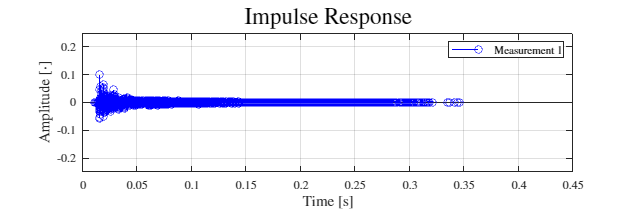

% MED STEM
f = figure('Position', [10 10 900 300]);
signal = [IR(1).Time IR(1).Amplitude];
signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
p = stem(signal(:, 1), signal(:, 2));
p.Color = colors(1, :);
hold off
grid on;
xlim([0 0.45])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 1', 'Location', 'northeast')

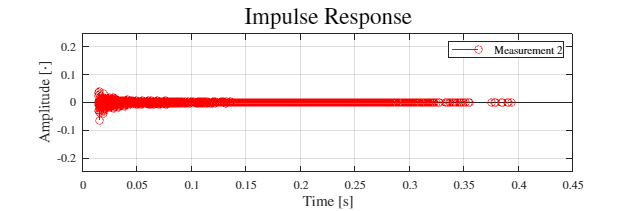

%exportgraphics(f, 'Figures/ImpulseResponse_Meas1.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
signal = [IR(2).Time IR(2).Amplitude];
signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
p = stem(signal(:, 1), signal(:, 2));
p.Color = colors(2, :);
hold off
grid on;
xlim([0 0.45])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 2', 'Location', 'northeast')

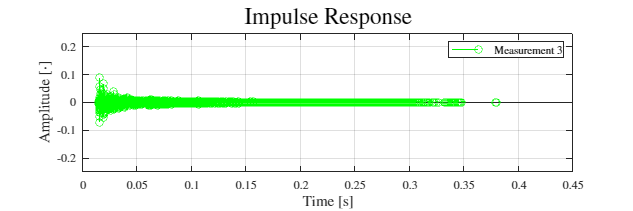

%exportgraphics(f, 'Figures/ImpulseResponse_Meas2.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
signal = [IR(3).Time IR(3).Amplitude];
signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
p = stem(signal(:, 1), signal(:, 2));
p.Color = colors(3, :);
hold off
grid on;
xlim([0 0.45])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 3', 'Location', 'northeast')

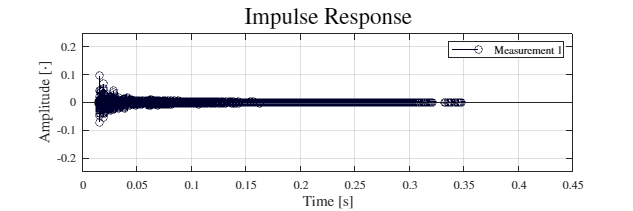

%exportgraphics(f, 'Figures/ImpulseResponse_Meas3.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
signal = [IR(4).Time IR(4).Amplitude];
signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
p = stem(signal(:, 1), signal(:, 2));
p.Color = colors(4, :);
hold off
grid on;
xlim([0 0.45])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 1', 'Location', 'northeast')

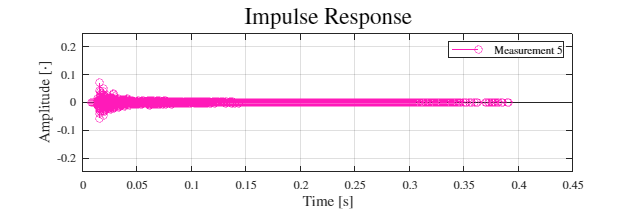

%exportgraphics(f, 'Figures/ImpulseResponse_Meas4.pdf', 'Resolution', 300);

f = figure('Position', [10 10 900 300]);
signal = [IR(5).Time IR(5).Amplitude];
signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
p = stem(signal(:, 1), signal(:, 2));
p.Color = colors(5, :);
hold off
grid on;
xlim([0 0.45])
ylim([-0.25 0.25])
title('Impulse Response', 'FontSize', SETTINGS.titleFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
legend('Measurement 5', 'Location', 'northeast')

%exportgraphics(f, 'Figures/ImpulseResponse_Meas5.pdf', 'Resolution', 300);